% param
flux_chaleur=-50;  % -phi/lambda
Tini=25; % temperature frontiere
Trad=100; % temperature resistance
h=1; % le pas

% matrice A
A1=diag(-4*ones(3,1))+diag(ones(2,1),-1)+diag(ones(2,1),1);
A2=diag(ones(1,3));
A3=zeros(3);
A123=[A1 A2 A3];
A456=[A2 A1 A2];
A789=[A3 A2 A1];
A=[A123;A456;A789]

A =     -4     1     0     1     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0
     0     1    -4     0     0     1     0     0     0
     1     0     0    -4     1     0     1     0     0
     0     1     0     1    -4     1     0     1     0
     0     0     1     0     1    -4     0     0     1
     0     0     0     1     0     0    -4     1     0
     0     0     0     0     1     0     1    -4     1
     0     0     0     0     0     1     0     1    -4



% imagesc(A)

% matrice C
C=zeros(9,1);
C([1 3],1)=-2*Tini;
C([2 4 6],1)=-Tini;
C([7 9],1)=-Tini-Trad+flux_chaleur;
C(8,1)=-Tini-Trad+flux_chaleur;
% imagesc(C)

% Tvec
Tvec=A\C

Tvec = 	1.0e+03 *

    0.3882
    0.5246
    0.3882
    0.9781
    1.2969
    0.9781
    2.2025
    2.7067
    2.2025


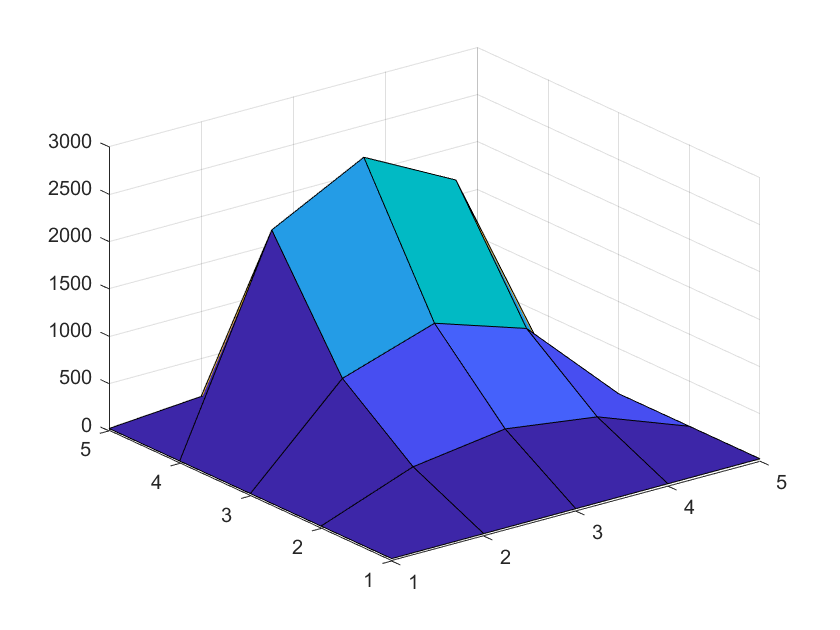


% T
T=zeros(5);
T(5,:)=Trad;
T(:,1)=Tini;
T(:,5)=Tini;
T(1,:)=Tini;
T(2,2:4)=Tvec(1:3,1);
T(3,2:4)=Tvec(4:6,1);
T(4,2:4)=Tvec(7:9,1);
surf(T)


[X,Y]=meshgrid(1:h:5,1:h:5);
figure(1)
surf(X,Y,T)

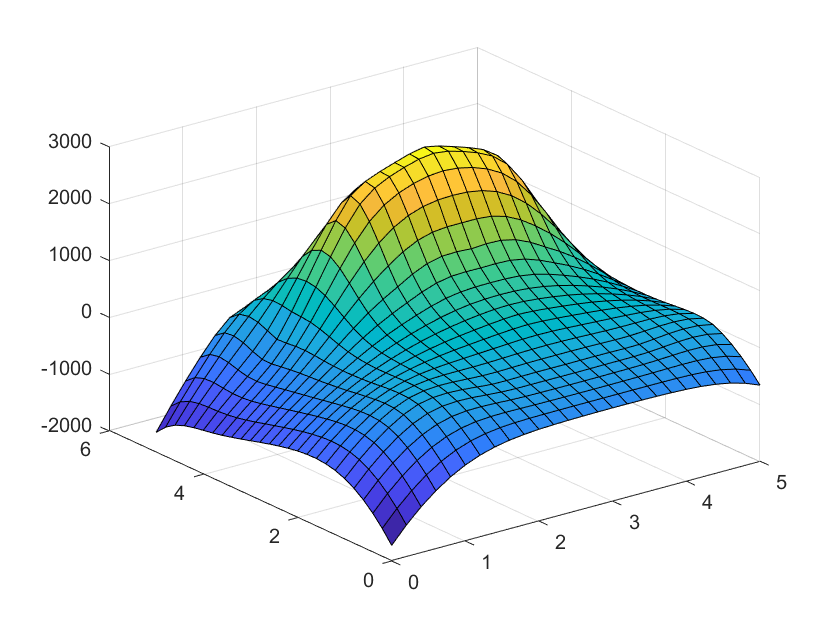


figure(2)
[xq,yq] = meshgrid(0:.2:5, 0:.2:5);
vq = griddata(X,Y,T,xq,yq,'v4');
surf(xq,yq,vq)